# Bilevel optimization - Simultaneously fitting background and a parameter-free distance distribution

#### Author: Luis Fabregas

An example of fitting dipolar data in one step using bilevel optimization, with a model that contains a parametric background and a parameter-free distribution.

## Simulate the data

Let's start by creating a simple 4-pulse DEER signal.

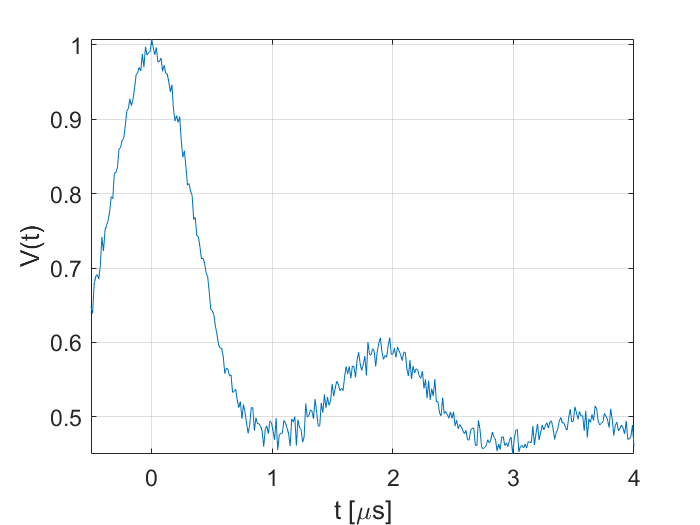

clear,clc,clf

% Axis definition
t = linspace(-0.5,4,350);
r = linspace(2,6,200);

% Distribution parameters
rmean = 4.5;
width = 0.3;

% Background parameters
k = 0.06;
d = 2.89;
lam = 0.4;

% Generate components
P = rd_onegaussian(r,[rmean width]);
B = td_strexp(t,[k d]);
V = dipolarsignal(t,r,P,'moddepth',lam,'background',B,'noiselevel',0.01);

plot(t,V)
xlabel('t [\mus]')
ylabel('V(t)')
axis tight, grid on, box on
set(gca,'FontSize',14)

## Plan the analysis

The first step for every analysis requires to think about what we actually need to fit and how. In our case, we would like to extract the distance distribution as well as the stretched exponential background from a simple 4-pulse DEER signal. Therefore, we want the distance distribution `Pfit`, the modulation depth` lambda`, the background decay rate `k`, and the fractal dimension `d`. The distance distribution is parameter free, and the background is a parametric model. Therefore, for the fit we can use bilevel optimization with the following setting:

Upper level:  `k, d, lambda (`using` fitparamodel`)

Lower level:  `P` `(`using` fitregmodel`)

We will use the `fitparamodel` function to fit the parameter set {`k,d,lambda`} while it calls a function which will create a model of the time-domain signal using an optimized P`fit` obtained via `fitregmodel`.

## Prepare the lower level fit

The next step requires the preparation of the lower level fit, i.e. the fit of the distance distribution (given fixed time-domain parameters) using Tikhonov regularization. This must be defined as a separate function, let's call `mymodel`. Define it either in a separate file or at the bottom of the script. Scroll down to see the function definition. 

Since the `fitparamodel` requires functions of the form `fcn(t,param)`, we wrap `mymodel` with a function handle with reduced inputs.

% Prepare function handle
myfcn = @(t,param)mymodel(t,param,V,r);

## Prepare the upper level fit

Since the upper level is responsible for the fit of the parameter set, we need to prepare its definition accordingly. We have three parameters: `k,d `and `lambda.` Since it is a custom-defined function we must provide some inital guess values and search range boundaries. For this, it is usually sufficient to visually inspect the experimental signal and guess the values.

% Parameter Set
% Index:  1  2  3
% Name:   k  d  lambda
param0 = [0.1 3 0.5];
lower  = [0.0 2 0.3]; 
upper  = [0.2 4 0.6]; 

Now we are ready to launch the bilevel optimization. To do so we call the `fitparamodel` function

%Launch bilevel optimization
paramfit = fitparamodel(V,myfcn,t,param0,'Lower',lower,'Upper',upper,'TolFun',1e-6);

It is important to remember that the tolerance value `TolFun` does not require to be as low as for typical parametric model fits. Starting with larger values in the range `1e-5` to `1e-9` is usually a good practice. For a final fit, the tolerance can be set to much lower values.

Once bilevel optimization has found an answer, we will get the fitted parameter set `paramfit` back. With this values, we can quickly obtain the time-domain and distance-domain fits

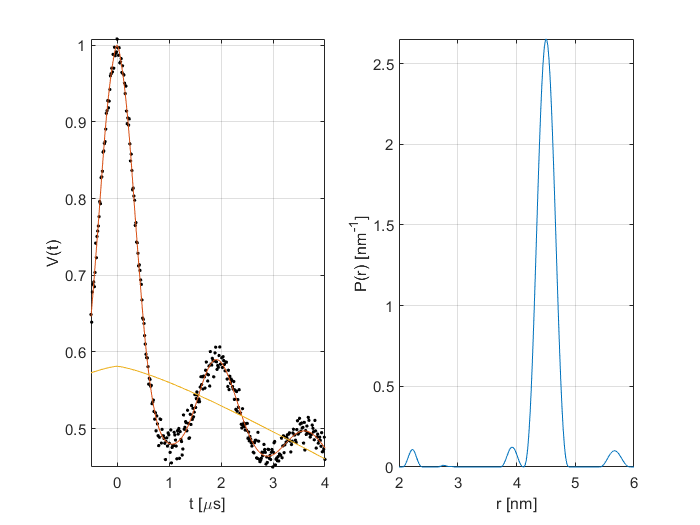

%Recover the fits
[Vfit,Pfit,Bfit] = mymodel(t,paramfit,V,r);

Once bilevel optimization has found an answer, we can plot the results

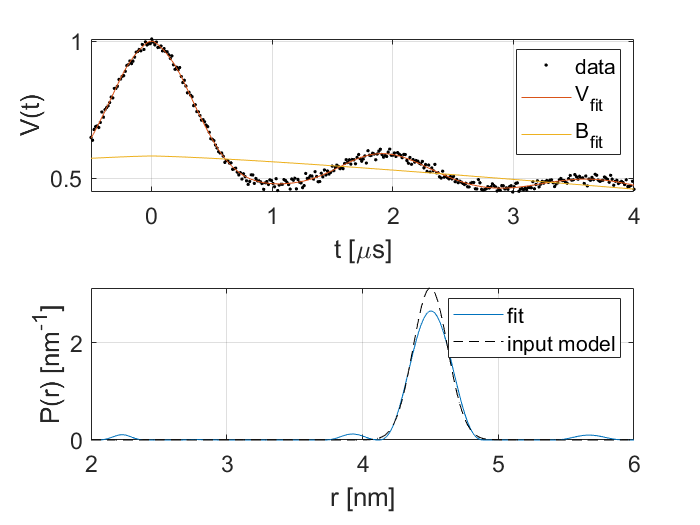

%Plot the bilevel optimization results
subplot(211)
plot(t,V,'k.',t,Vfit,t,Bfit)
axis tight, grid on, box on
xlabel('t [\mus]')
ylabel('V(t)')
legend('data','V_{fit}','B_{fit}')
set(gca,'FontSize',14)
subplot(212)
plot(r,Pfit,r,P,'k--')
axis tight,grid on, box on
xlabel('r [nm]')
ylabel('P(r) [nm^{-1}]')
legend('fit','input model')
set(gca,'FontSize',14)

## Prepare the lower-level function (continued) 

The lower-level function must accept the parameter set `param` passed down by the upper level and construct a current model for the signal given these parameters. The function must return the time-domain fit of the signal as a first output in order to compare it to the experimental data in the upper level. Still, we can define further outputs without interfering with the fit. Let's start by defining the lower-level function `mymodel` as follows. The function must accept (at least) the time-axis `t` and the parameter set `param` to work, but make sure to pass all other arguments required for the function. 

function [Vfit,Pfit,Bfit] = mymodel(t,param,V,r)
% Extract the parameters
k = param(1);
d = param(2);
lam = param(3);

Now that we have the upper-level parameters in our function, we construct the trial background function and the corresponding dipolar kernel

% Construct the background
Bfit = td_strexp(t,[k,d]);
% Generate the dipolar kernel
KB = dipolarkernel(t,r,lam,Bfit);

With the kernel in hand, we proceed to fit the distance distribution under the current parameter set using AIC-Tikhonov regularization. This gives `Pfit`, and using the kernel we then calculate the fitted dipolar signal, `Vfit.`

% Get distance-domain fit
Pfit = fitregmodel(V,KB,r,'tikhonov','aic');
% Get time-domain fit
Vfit = KB*Pfit;

We can also plot the current results, to diplay the progress of the fitting. To force MATLAB to plot at each iteration, we must use the `drawnow` command after plotting.

% Plot intermediate results
subplot(121)
Bfit = (1-lam)*Bfit;
plot(t,V,'k.',t,Vfit,t,Bfit)
axis tight, grid on, box on
xlabel('t [\mus]')
ylabel('V(t)')
subplot(122)
plot(r,Pfit)
axis tight,grid on, box on
xlabel('r [nm]')
ylabel('P(r) [nm^{-1}]')
drawnow
end